# Author: Lu, Chia-Feng 2013.11.28

clear, close all
clc

## create data

X = [2.50  2.40;
     0.50  0.70;
     2.20  2.90;
     1.90  2.20;
     3.10  3.00;
     2.30  2.70;
     2.00  1.60;
     1.00  1.10;
     1.50  1.60;
     1.10  0.90];  %[x1 x2]

[n, m] = size(X);   % n measurements; m variables 
 
X = X - ones(n,1)*mean(X,1);   % subtract mean

CovX = cov(X)

CovX =     0.6166    0.6154
    0.6154    0.7166


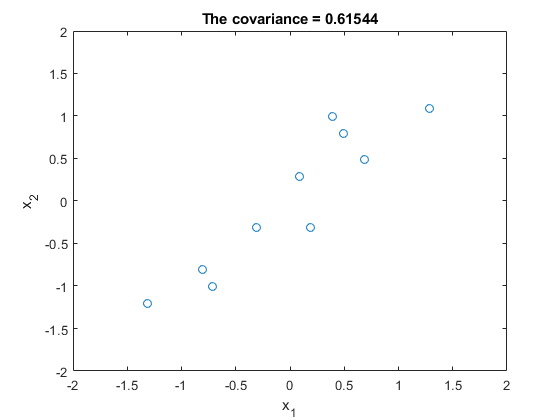


figure, plot(X(:,1),X(:,2),'o')
xlabel('x_1'),ylabel('x_2')
title(['The covariance = ' num2str(CovX(2))])
axis([-2 2 -2 2])

## calculate eigenvalues and eigenvectors

[eigVec,eigVal]=eig(CovX)

eigVec =    -0.7352    0.6779
    0.6779    0.7352


eigVal =     0.0491         0
         0    1.2840


eigVec=fliplr(eigVec);

## project data to the eigenvectros

PCfull = X * eigVec;         % project data using full eigVec

Covfull = cov(PCfull)

Covfull =     1.2840    0.0000
    0.0000    0.0491


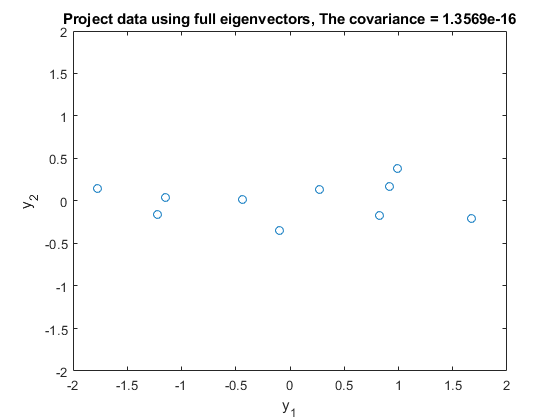


figure, plot(PCfull(:,1),PCfull(:,2),'o')
xlabel('y_1'),ylabel('y_2')
title(['Project data using full eigenvectors, The covariance = ' num2str(Covfull(2))])
axis([-2 2 -2 2])

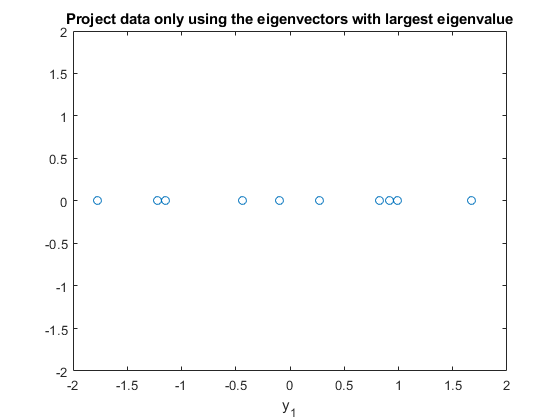


PClarge = X * eigVec(:,1);  % project data only using the eigVec with largest eighVal

figure, plot(PClarge(:,1),zeros(n,1),'o')
title('Project data only using the eigenvectors with largest eigenvalue')
xlabel('y_1')
axis([-2 2 -2 2])

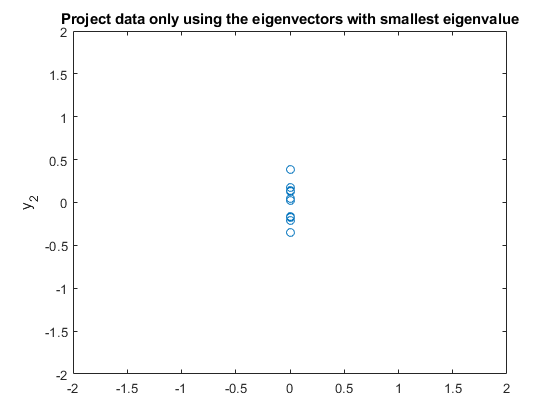


PCsmall = X * eigVec(:,end);  % project data only using the eigVec with smallest eighVal

figure, plot(zeros(n,1),PCsmall(:,1),'o')
title('Project data only using the eigenvectors with smallest eigenvalue')
ylabel('y_2')
axis([-2 2 -2 2])

## reconstruct new X only using 1st eigenvector

newX = PClarge * eigVec(:,1)';
       
CovnewX = cov(newX)

CovnewX =     0.5900    0.6399
    0.6399    0.6940


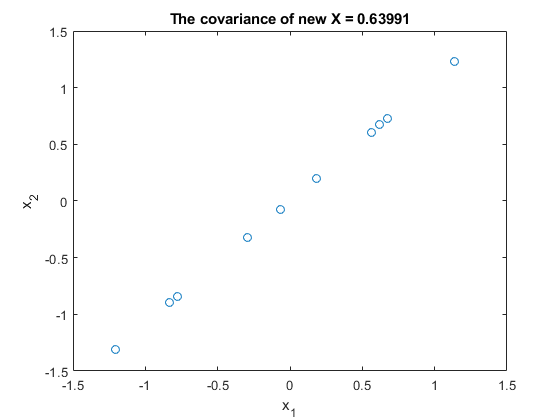


figure, plot(newX(:,1),newX(:,2),'o'), hold on
title(['The covariance of new X = ' num2str(CovnewX(2))])
xlabel('x_1'),ylabel('x_2')